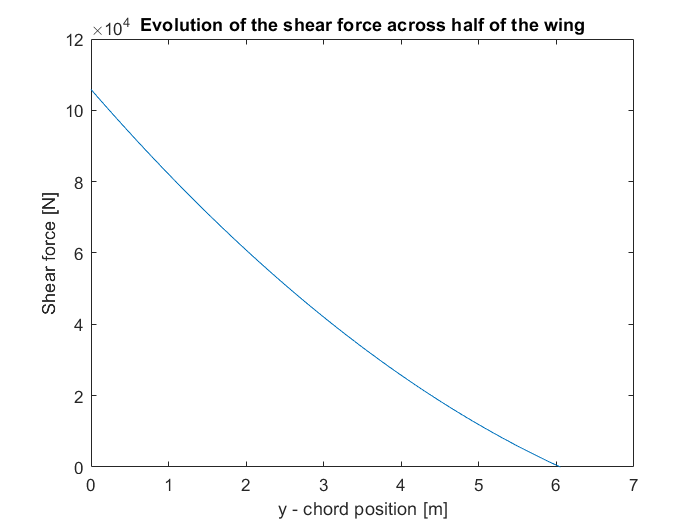

W = 333.954*9.81;
L = 214995;
b = 12.1;
lambda = 0.4;

y = 0:0.01:b/2;

V = (2*(L-W)/(b*(1+lambda)))*(b/2-y).*(1-((1-lambda)/b)*(b/2+y));

M = (2*(L-W)/(b*(1+lambda)))*((b/2)*(b/2-y)-((b/2)^2-y.^2)/2-((1-lambda)*b/4)*(b/2-y)+((1-lambda)/(3*b))*((b/2)^3-y.^3));

figure(1)
plot(y,V)
hold on
xlabel('y - chord position [m]')
ylabel('Shear force [N]')
title('Evolution of the shear force across half of the wing')
hold off

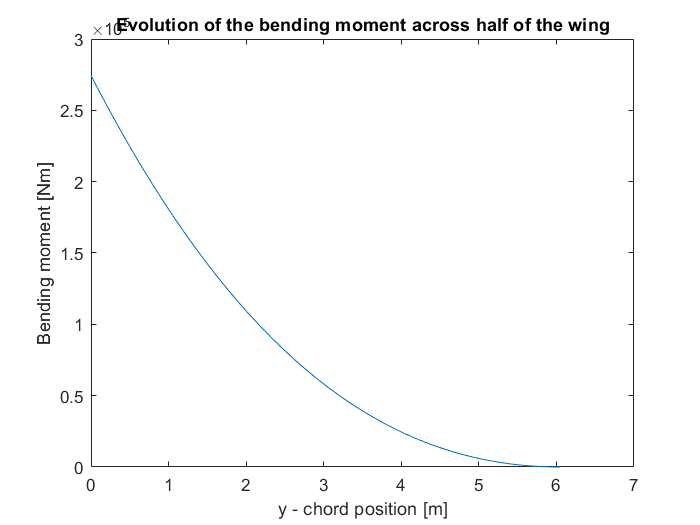


figure(2)
plot(y,M)
hold on
xlabel('y - chord position [m]')
ylabel('Bending moment [Nm]')
title('Evolution of the bending moment across half of the wing')
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear
clc

W = 333.954*9.81;
L = 214995;
b = 12.1;
lambda = 0.4;

syms y

V = (2*(L-W)/(b*(1+lambda)))*(b/2-y)*(1-((1-lambda)/b)*(b/2+y))

$$V = \left(\frac{6\,y}{121}-\frac{7}{10}\right)\,\left(\frac{858867343382693\,y}{34359738368}-\frac{103922948549305853}{687194767360}\right)$$


M = (2*(L-W)/(b*(1+lambda)))*((b/2)*(b/2-y)-((b/2)^2-y^2)/2-((1-lambda)*b/4)*(b/2-y)+((1-lambda)/(3*b))*((b/2)^3-y^3))

$$M = -\frac{858867343382693\,y^{3}}{2078764171264}+\frac{858867343382693\,y^{2}}{68719476736}-\frac{727460639845140971\,y}{6871947673600}+\frac{2509419604222607982176079843302473}{9142501510835633133715456000}$$


V = simplify(V);
M = simplify(M);
V = vpa(V,12)

$$V = \left(24996.3295466\,y-151227.793757\right)\,\left(0.0495867768595\,y-0.7\right)$$

M = vpa(M,12)

$$M = -413.162471845\,y^{3}+12498.1647733\,y^{2}-105859.45563\,y+274478.445669$$